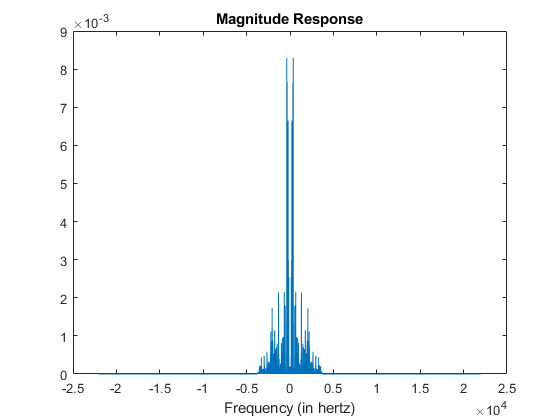

[S,Fs] = audioread('Music library\Cut down 30s\cute cut.mp3');   
% [S,Fs] = audioread('Music library\Vacuum.mp3');

S = mean(S,2);  
halfMORT = numel(S) / 4;
S(halfMORT:end,:) = [];
% matrixOfRecordedTracks = matrixOfRecordedTracks(1:halfMORT,:);

% S = bandstop(S,[90 130], Fs);
% S = bandstop(S,[480 510], Fs);
% S = lowpass(S,[4000 4100],Fs);

S = filter(part1,S);
S = filter(part2,S);
S = filter(part3,S);


hplayer = audioplayer(S, Fs);
play(hplayer);


N = size(S,1); % sample lenth
slength = N/Fs;

Fc   = 1E+3;                                     % Frequency (Hz)
t   = linspace(0, slength, N );  

   %%Sine wave:
%    Fc = 12;                       % hertz
%    x = cos(2*pi*Fc*t);
   x = S;
   %%Fourier Transform:
   X = fftshift(fft(x));

   %%Frequency specifications:
   dF = Fs/N;                      % hertz
   f = -Fs/2:dF:Fs/2-dF;           % hertz
    var = abs(X)/N;
   
   %%Plot the spectrum:
   figure;
   plot(f,var);
   xlabel('Frequency (in hertz)');
   title('Magnitude Response');

   
   
   
   
   
   
   
   
   
   
% [z,fs]=audioread('Music library\5 second a new beginning - Copy.mp3'); 
% [z1,fs1]=audioread('Music library\Vacuum-A1-www.fesliyanstudios.com.mp3');
% z = mean(z,2);
% z1 = mean(z1,2);
% track=fft(z); %fft of input signal
% vac=fft(z1); %fft of input signal
% hold on
% plot(abs(vac))
% plot(abs(track))
% 
% 
% subplot(2,1,1);plot(abs(vac));
% title('vac');
% xlabel('frequency');ylabel('magnitude');
% subplot(2,1,2);plot(abs(track));
% title('track');
% xlabel('frequency');ylabel('magnitude');
% 
% 
% 
% 
% % 
% % wn=[4000 8000]/(fs/2);   %bandpass
% % [b,a]=butter(6,wn);
% % fvtool(b,a);
% % f=filter(b,a,z);
% % afil=fft(f);
% % subplot(2,1,1);plot(real(bfil));
% % title('frequency respones of input signal');
% % xlabel('frequency');ylabel('magnitude');
% % subplot(2,1,2);plot(real(afil));
% % title('frequency respones of filtered signal');
% % xlabel('frequency');ylabel('magnitude');